% Simple test

load('C:\Users\Lenovo\postdoc\DATA\TEMP\3_2023-11-22_11_34_44resRun.mat')
ix =7;
oS = resRun{ix}.oS;
barcodeGen = bG{ix};

## Parameters for the run. Check that these to be the same as Table 2 in the paper

alphaNu = 0.075; % 0.08 default for the paper
sets.minOverlap = 300;
sets.scDiffSetting = 0.04;
sets.pxDifSetting = 50;
showFig = 1; % whether to show output figure
pthresh =  0.01;

timestamp = datestr(clock(), 'yyyy-mm-dd_HH_MM_SS'); % timestamp for results

both on local and global. Only uses the oS structure as input + parameters from table 2

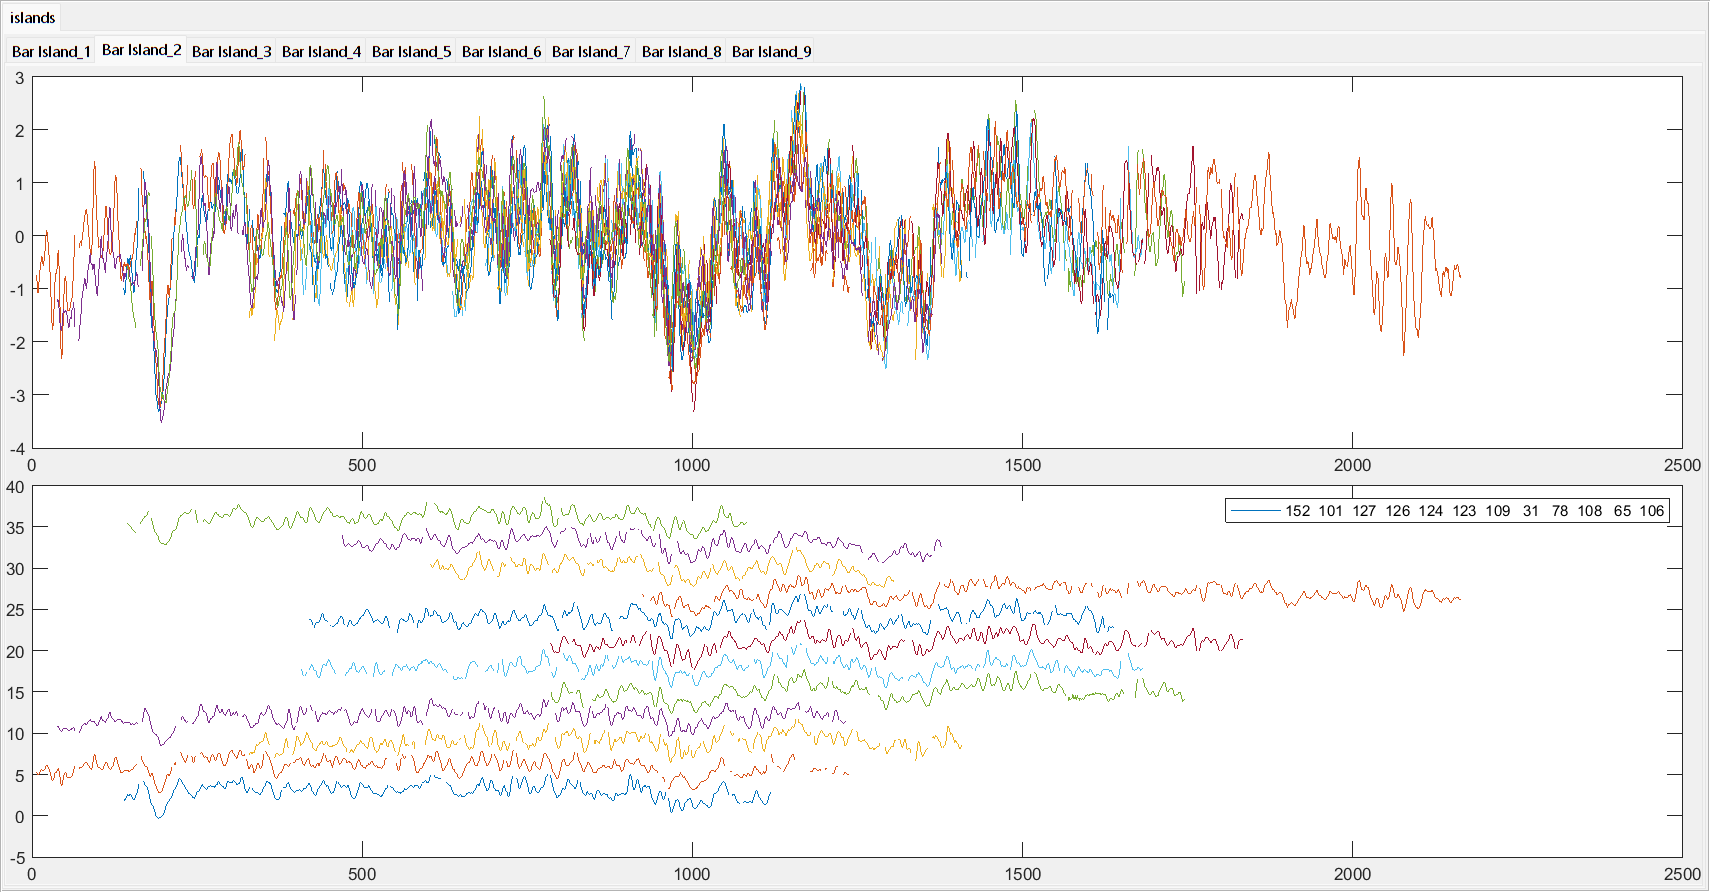

[sortedVals, sortedIds,localScore,partialScore,lenA,lenB,partialLength,pvalLocal,pvalLeftOver, pvalCombined, sortedValsBad, sortedIdsBad] = ...
    calculate_sorted_pvals(oS,sets.minOverlap, alphaNu,pthresh); %localCCStruct

sortedValsGood = sortedVals(~isnan(sortedVals));
sortedIdsGood  = sortedIds(~isnan(sortedVals));
localScore = localScore(~isnan(sortedVals));

% sortedValsGood(4190:end) = nan; % change alphaNu instead of this

% Main barcode islands script:

import Core.barcode_island_output;
[barsetGen, outConsensus, coverage, consensus, islandElts, islandPx,cGenAll,barcodeIslandsData, barStruct,barIslands] =...
    barcode_island_output(sortedValsGood,sortedIdsGood, oS, barcodeGen,timestamp,sets.scDiffSetting,sets.pxDifSetting, [],showFig);

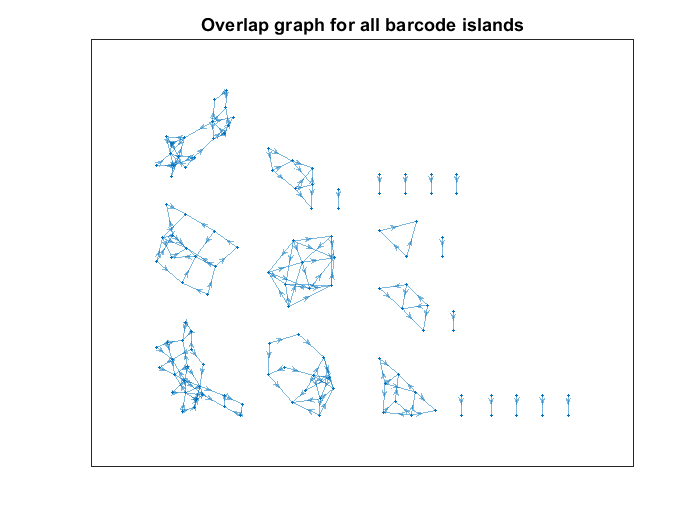

%     nonEmpty= find(cellfun(@(x) length(x.members)>2,    barsetGen.barcodeIslands)); % keep only non-empty

% nonEmpty= find(cellfun(@(x) ~isempty(x),    barsetGen.consistencyCheck)); % keep only non-empty
accepted = cellfun(@(x) x.accepted, barsetGen.currentData); % all the

import Core.create_graph_from_barsetgen;
[Gtemp,GtempOrig] =   create_graph_from_barsetgen(barsetGen,barcodeGen,[],showFig);


f=figure('Position', [10 10 900 600]); g=tiledlayout(7,2,'TileSpacing','tight','Padding','none');
% fig = gcf;
% fig.PaperSize=[21 29.7];
% fig.PaperPosition = [1 1 20 25];

idxPair = 70;
[curSink,curSource] = ind2sub(size(oS),sortedIds(idxPair));
import Plot.pair_evaluation_with_ground_truth_simple_plot; % todo: convert comparisonStructC to overlap for this plot (using something like synth_to_struct)
pair_evaluation_with_ground_truth_simple_plot(barcodeGen, oS,curSink,curSource,[],[],g);


nexttile([1 2]) % Stouffer scores, Good, bad, & scores that are put into islands

% plot(sortedVals,'o','Color',[0 0.4470 0.7410])
hold on
histogram(sortedVals,'EdgeAlpha',0,'BinLimits',[-5 10],'BinWidth',0.5)
histogram(sortedValsBad,'EdgeAlpha',0,'BinLimits',[-5 10],'BinWidth',0.5)
histogram(sortedValsGood(logical(accepted)),'EdgeAlpha',0,'BinLimits',[-5 10],'BinWidth',0.5)

grid on
grid minor
lgd = legend({'$s_{combined, good}$ ','$s_{combined, bad}$ ','$s_{islands}$'},'Interpreter','latex')

lgd =   Legend ($s_{combined, good}$, $s_{combined, bad}$, $s_{islands}$) with properties:

         String: {'$s_{combined, good}$'  '$s_{combined, bad}$'  '$s_{islands}$'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 7.2000
       Position: [0.7631 0.7418 0.1103 0.0659]
          Units: 'normalized'

  Show all properties


lgd.Location = 'eastoutside';
set(gca, 'YScale', 'log')
title(['(B) Stouffer scores, pval=', num2str(pthresh)],'Interpreter','latex')

totalDegree = indegree(GtempOrig) + outdegree(GtempOrig);
% Find nodes with total degree less than 2
nodesToRemove = find(totalDegree < 2);
allNodes = 1:numnodes(GtempOrig);
allNodes(nodesToRemove) = [];
G_removed = rmnode(GtempOrig, nodesToRemove);

lettersAll = mat2cell('A':'Z',1,ones(1,26));

letters = lettersAll(3:end);
for idx=1:3%length(outConsensus)
    nexttile([1 1]) % graphs
    indicesCell = arrayfun(@(x) logical(allNodes == x),  barIslands{idx}, 'UniformOutput', false);

    allNodesKeep = sum(cell2mat(indicesCell'));
    % remove all except these
    G_representation = rmnode(G_removed, find(~allNodesKeep));

    h=plot(G_representation,'Layout','force','ArrowSize',5,'MarkerSize',1);
% 
% highlight(h, indicesCell, 'NodeColor', 'r');
% 
title(['(' letters{idx} ') Graph representation (', num2str(idx),')'], 'Interpreter','latex')
end
%

maxConsensus = max(cellfun(@(x) size(x,2),outConsensus));
% hold on

letters = lettersAll(5:end)

letters = 1×22 cell array
    {'E'}    {'F'}    {'G'}    {'H'}    {'I'}    {'J'}    {'K'}    {'L'}    {'M'}    {'N'}    {'O'}    {'P'}    {'Q'}    {'R'}    {'S'}    {'T'}    {'U'}    {'V'}    {'W'}    {'X'}    {'Y'}    {'Z'}


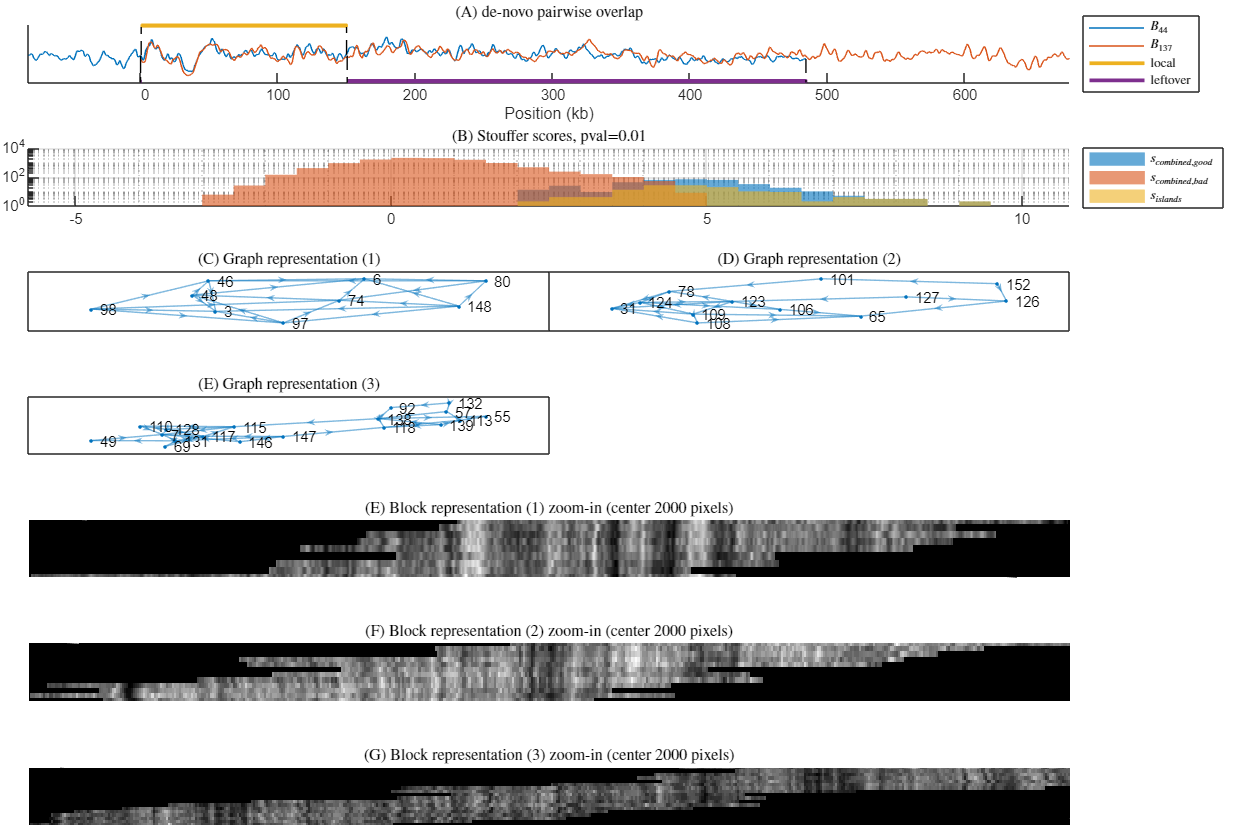

for idx=1:3%length(outConsensus)
    nexttile([1 2])
hold on
title(['(' letters{idx} ') Block representation (', num2str(idx),') zoom-in (center 2000 pixels)'], 'Interpreter','latex')


% sort based on starting position
[pos,idxv] = sort(arrayfun(@(x) find(~isnan(outConsensus{idx}(x,:)),1,'first') +(find(~isnan(outConsensus{idx}(x,:)),1,'last')-find(~isnan(outConsensus{idx}(x,:)),1,'first'))/2,1:size(outConsensus{idx},1)));
% 
consensusToPlot1 = outConsensus{idx}(idxv,:);

% zoomin
% consensusToPlot1 = consensusToPlot1(:,[size(consensusToPlot1,2)/2-1000:size(consensusToPlot1,2)/2+1000]);
consensusToPlot1 = consensusToPlot1(find(sum(~isnan(consensusToPlot1'))),:);

imagesc(consensusToPlot1);colormap(gray)
% xlim([1 size(consensusToPlot1,2)])
ylim([1 size(consensusToPlot1,1)])
% xlim([size(consensusToPlot1,2)/2-1000 size(consensusToPlot1,2)/2+1000])

% imagesc(outConsensus{idx}(idxv,:));colormap(gray)
axis off

set(gca,'xtick',[])

xlim([1 2000])

% xlim([1 maxConsensus])
end

%








